%%% Not suitable
% RM8/I - Low winding area
% RM12/I-3F4-E250 - High Inductance
% P22/13/I-3F46 - Low winding area, Low inductance

%%% Inductor Design with FerroxCube 3F3 Material

deltaI = 28/2; %A
Iavg = 10;
Irms = 13.2;
L = 6.8e-6; %H
ThickPaper = 91e-6; %m
mo = 4*pi*10^-7;
Acable = 3e-6; % m^2
Dcable = 2*sqrt(Acable/pi)*1e3; %mm
FF = 0.5;
Rcable = 5/60; %mOhm per mm


% Case 1 - E32/6/20/R-3F36
%http://ferroxcube.home.pl/prod/assets/e32620r.pdf
Lgap = 2*8*ThickPaper;
Ae = 130e-6; %m^2
R = Lgap/mo/Ae;
N = ceil(sqrt(L*R));
fprintf('Turn number for E32/6/20/R-3F36 is %d',N)

Turn number for E32/6/20/R-3F36 is 8

Ldes = N^2/R;
fprintf('Resulting inductance of E32/6/20/R-3F36 is %f in uH',Ldes/1e-6)

Resulting inductance of E32/6/20/R-3F36 is 7.180783 in uH

Bac = N*deltaI*mo/Lgap;
fprintf('AC Flux density for E32/6/20/R-3F36 is %f in mT',Bac*10^3)

AC Flux density for E32/6/20/R-3F36 is 96.664389 in mT

Bdc = N*10*mo/Lgap;
fprintf('DC Flux density for E32/6/20/R-3F36 is %f in mT',Bdc*10^3)

DC Flux density for E32/6/20/R-3F36 is 69.045992 in mT

Awind = Acable*N/0.5;
FF1 = Acable*10^6*N/58.9;
fprintf('Winding area for E32/6/20/R-3F36 is %f in mm2',Awind*10^6)

Winding area for E32/6/20/R-3F36 is 48.000000 in mm2


MLT = 80;
RwindingDC = Rcable*MLT*N;
RwindingAC = 1.5 * RwindingDC;
PwindingDC = Iavg^2*RwindingDC;
PwindingAC = (Irms)^2*RwindingAC;
Pwinding1 = PwindingAC;
fprintf('Total winding loss is %f in mW',Pwinding1)

Total winding loss is 13939.200000 in mW


Psp = 0.7*10^3; % kW/m^3
Ve = 4560; %mm^3
Pcore1 = Psp*1e3 * Ve/1e9;

fprintf('Total core loss is %f in W',Pcore1)

Total core loss is 3.192000 in W


% Case 2 - E65/32/27-3F3
% https://ferrite.ru/uploads/pdf/products/ferroxcube/materials/3f3.pdf
Lgap = 2*8*ThickPaper;
Ae = 540e-6; %m^2
R = Lgap/mo/Ae;
N = ceil(sqrt(L*R));
fprintf('Turn number for 432202501601 is %d',N)

Turn number for 432202501601 is 4

Bac = N*deltaI*mo/Lgap;
fprintf('AC Flux density for 432202501601 is %f in mT',Bac*10^3)

AC Flux density for 432202501601 is 48.332195 in mT

Bdc = N*10*mo/Lgap;
fprintf('DC Flux density for 432202501601 is %f in mT',Bdc*10^3)

DC Flux density for 432202501601 is 34.522996 in mT

Awind = Acable*N/0.5;
FF2 = Acable*10^6*N/394;
fprintf('Winding area for 432202501601 is %f in mm2',Awind*10^6)

Winding area for 432202501601 is 24.000000 in mm2


MLT = 150;
RwindingDC = Rcable*MLT*N;
RwindingAC = 1.5 * RwindingDC;
PwindingDC = Iavg^2*RwindingDC;
PwindingAC = (Irms)^2*RwindingAC;
Pwinding2 = PwindingAC;
fprintf('Total winding loss is %f in mW',Pwinding2)

Total winding loss is 13068.000000 in mW


Psp = 2.1*10^2; % kW/m^3
Ve = 79000; %mm^3
Pcore2 = Psp*1e3 * Ve/1e9;

fprintf('Total core loss is %f in W',Pcore2)

Total core loss is 16.590000 in W


% Case 3 - E38/8/25-3F36
%https://www.ferroxcube.com/upload/media/product/file/Pr_ds/E38_8_25_PLT38_25_3.8.pdf
Lgap = 2*7*ThickPaper;
Ae = 194e-6; %m^2
R = Lgap/mo/Ae;
N = ceil(sqrt(L*R));
fprintf('Turn number for E38/8/25-3F36 is %d',N)

Turn number for E38/8/25-3F36 is 6

Ldes = N^2/R;
fprintf('Resulting inductance of E38/8/25-3F36 is %f in uH',Ldes/1e-6)

Resulting inductance of E38/8/25-3F36 is 6.888817 in uH

Bac = N*deltaI*mo/Lgap;
fprintf('AC Flux density for E38/8/25-3F36 is %f in mT',Bac*10^3)

AC Flux density for E38/8/25-3F36 is 82.855191 in mT

Bdc = N*10*mo/Lgap;
fprintf('DC Flux density for E38/8/25-3F36 is %f in mT',Bdc*10^3)

DC Flux density for E38/8/25-3F36 is 59.182279 in mT

Awind = Acable*N/0.5;
FF3 = Acable*10^6*N/100.7;
fprintf('Winding area for E38/8/25-3F36 is %f in mm2',Awind*10^6)

Winding area for E38/8/25-3F36 is 36.000000 in mm2


MLT = 101;
RwindingDC = Rcable*MLT*N;
RwindingAC = 1.5 * RwindingDC;
PwindingDC = Iavg^2*RwindingDC;
PwindingAC = (deltaI/2/sqrt(3))^2*RwindingAC;
Pwinding3 = PwindingAC + PwindingDC;
fprintf('Total winding loss is %f in mW',Pwinding3)

Total winding loss is 6287.250000 in mW


Psp = 0.55*10^3; % kW/m^3
Ve = 10200; %mm^3
Pcore3 = Psp*1e3 * Ve/1e9;

fprintf('Total core loss is %f in W',Pcore3)

Total core loss is 5.610000 in W




% Case 4 - E64/10/50-3F4
% https://elnamagnetics.com/wp-content/uploads/library/Ferroxcube-Materials/3F4_Material_Specification.pdf
Lgap = 2*6*ThickPaper;
Ae = 519e-6; %m^2
R = Lgap/mo/Ae;
N = ceil(sqrt(L*R));
Ldes = N^2/R;
fprintf('\nTurn number for E64/10/50-3F4 is %d',N)


Turn number for E64/10/50-3F4 is 4

Bac = N*deltaI*mo/Lgap;
fprintf('AC Flux density for E64/10/50-3F4 is %f in mT',Bac*10^3)

AC Flux density for E64/10/50-3F4 is 64.442926 in mT

Bdc = N*Iavg*mo/Lgap;
fprintf('DC Flux density for E64/10/50-3F4 is %f in mT',Bdc*10^3)

DC Flux density for E64/10/50-3F4 is 46.030662 in mT

Awind = Acable*N/0.5;
FF4 = Acable*10^6*N/222;
fprintf('Winding area for E64/10/50-3F4 is %f in mm2',Awind*10^6)

Winding area for E64/10/50-3F4 is 24.000000 in mm2


MLT = 165.6;
RwindingDC = Rcable*MLT*N;
RwindingAC = 1.5 * RwindingDC;
PwindingDC = Iavg^2*RwindingDC;
PwindingAC = (Irms)^2*RwindingAC;
Pwinding4 = PwindingAC;
fprintf('Total winding loss is %f in mW',Pwinding4)

Total winding loss is 14427.072000 in mW


Psp = 500; % kW/m^3
Ve = 40700; %mm^3
Pcore4 = Psp*1e3 * Ve/1e9;

fprintf('Total core loss is %f in W',Pcore4)

Total core loss is 20.350000 in W



% Case 5 - E58/11/38-3F4
% https://elnamagnetics.com/wp-content/uploads/library/Ferroxcube-Materials/3F4_Material_Specification.pdf
Lgap = 2*9*ThickPaper;
Ae = 308e-6; %m^2
R = Lgap/mo/Ae;
N = ceil(sqrt(L*R));
Ldes = N^2/R;
fprintf('\nTurn number for E58/11/38-3F4 is %d',N)


Turn number for E58/11/38-3F4 is 6

Bac = N*deltaI*mo/Lgap;
fprintf('AC Flux density for E58/11/38-3F4 is %f in mT',Bac*10^3)

AC Flux density for E58/11/38-3F4 is 64.442926 in mT

Bdc = N*Iavg*mo/Lgap;
fprintf('DC Flux density for E58/11/38-3F4 is %f in mT',Bdc*10^3)

DC Flux density for E58/11/38-3F4 is 46.030662 in mT

Awind = Acable*N/0.5;
FF5 = Acable*10^6*N/272;
fprintf('Winding area for E58/11/38-3F4 is %f in mm2',Awind*10^6)

Winding area for E58/11/38-3F4 is 36.000000 in mm2


MLT = 134.3;
RwindingDC = Rcable*MLT*N;
RwindingAC = 1.5 * RwindingDC;
PwindingDC = Iavg^2*RwindingDC;
PwindingAC = (Irms)^2*RwindingAC;
Pwinding5 = PwindingAC;
fprintf('Total winding loss is %f in mW',Pwinding5)

Total winding loss is 17550.324000 in mW


Psp = 500; % kW/m^3
Ve = 40700; %mm^3
Pcore5 = Psp*1e3 * Ve/1e9;

fprintf('Total core loss is %f in W',Pcore5)

Total core loss is 20.350000 in W

## Figures

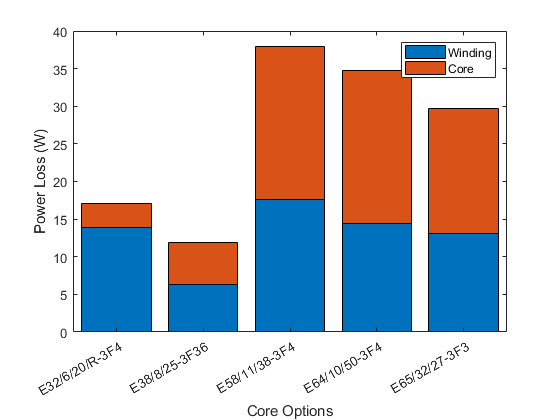

vals = [...
    Pwinding1/1e3 Pcore1;...
    Pwinding2/1e3 Pcore2;...
    Pwinding3/1e3 Pcore3;...
    Pwinding4/1e3 Pcore4;...
    Pwinding5/1e3 Pcore5;...

    ];
FFvals = [FF1*100 FF2*100  FF3*100 FF4*100 FF5*100];
x = categorical({'E32/6/20/R-3F4' 'E65/32/27-3F3' 'E38/8/25-3F36' 'E64/10/50-3F4' 'E58/11/38-3F4'});

figure
b1 = bar(x,vals,'stacked');
ylim([0 40])
ylabel('Power Loss (W)')
legend('Winding','Core')
xlabel('Core Options')

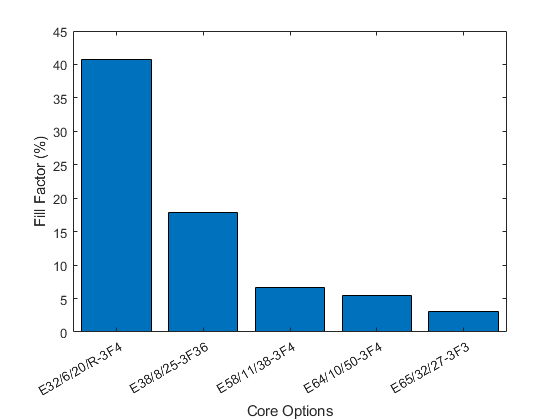


figure
b2 = bar(x,FFvals);
ylabel('Fill Factor (%)')
xlabel('Core Options')